% ds_validation.reset;
%ds = ds_validation;

ds_test.reset;
ds_test.augmentData = true;
ds = ds_test;
% ds = sub_ds_train;

% tested_net = best_net;
tested_net = net;
predictions_prob = [];
labels_all = [];
while ds.hasdata
    b = ds.read;
features = b.predictors;
labels = b.input;

predictions = predict(tested_net,features);
predictions = [predictions{:}];
predictions_prob_temp = predictions(2,:);
predictions_prob = [predictions_prob,predictions_prob_temp];


labels_temp =  [labels{:}];
labels_all = [labels_all,labels_temp];

end

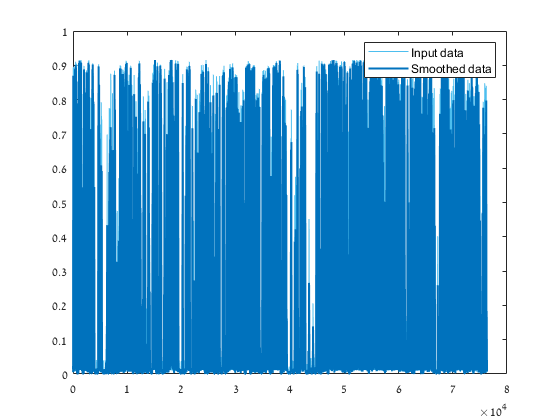

% Smooth input data
predictions_prob_smooth = smoothdata(predictions_prob,"gaussian",20);

% Display results
clf
plot(predictions_prob,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(predictions_prob_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

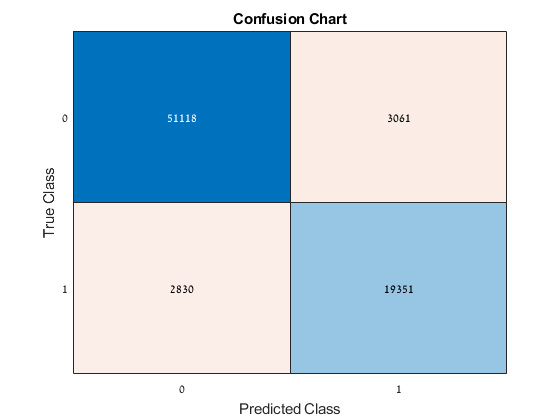

Accuracy: 0.922852
F1 Score: 0.867894
Precision: 0.863421
Recall: 0.872413


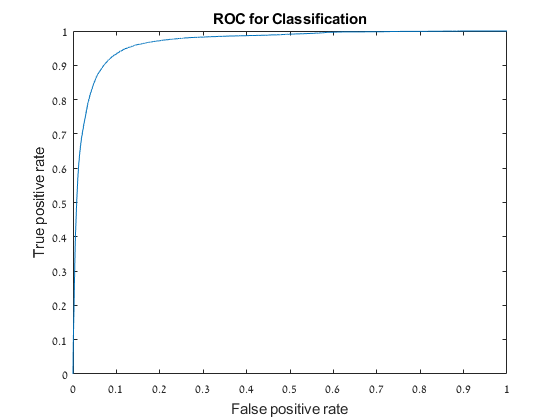

Area under curve: 0.968114
Best Th:0.323055



[acc,F1,C,AUC,Precision,Recall,optimalTh ]= plot_statistics2(predictions_prob,labels_all,0.32);